Symbolic math - Matlab

- Concept

Perform symbolic comutations from Matlab command line.

- plot:

Consider to plot a function as

                
$$f\left(x\right)=x^2 +3x+3$$


To plot $f\left(x\right)\;,x\in \left\lbrack -1\;,1\right\rbrack$, 

1)  numerically  

clear all
x = linspace(-1,1,100);
figure(1)
plot(x.^2+ 3*x + 3)

Here we may define the variable $x$ as sampled valued from -1 to 1 with 100 points. 

2) symbolic math

Now we may define symbolic object $x$ as

syms x
figure(2)
fplot(x^2+3*x+3, [-1 1], 'r')

in the symbolix math, the variable as "continuos variable" compared to "sampled point" in 1) case. Plot cmd is "fplot", function plot, rather than "plot".

            2. As a "variable"

 Consider 

            
$$y=2\frac{{\left(x+3\right)}^2 }{x^2 +6x+9}$$


then clearly $y=2$, 

clear all;
syms x
y = 2*(x+3)^2 / (x^2+ 6*x+9);
simplify(y)

The answer is the same as analytically. 

            3. Solve algebraic equation

Consider to find $x$ to satisfy the equation 

              
$$x+3=0$$
 

or 

            
$$x^2 \;+3x+2=0$$


clear all
syms x
eqn1 = x+3 == 0;
eqn2 = x^2 + 3*x +2 ==0 ;
S1 = solve(eqn1)
S2 = solve(eqn2)

Is it wonderful?  more in advance find the solution to the 2-nd order equation.

       
$$x^2 +\textrm{ax}+b=0$$


Here, not only $x$ but $a,b$ are symbolic objects. 

clear all
syms x a b
f = x^2 + a*x+ b ==0;
S1 =solve(f,x)
S2 = solve(f,a)

- **Ex.1: More a complicated example be considered. **Let         $f\left(V,V_0 ,R,C,T\right)=V-V_0 e^{\left(-\frac{T}{\textrm{RC}}\right)}$.

Find $R$ such that $f=0$

- Derivatives

Consider $f\left(x\right)=\sin \left(x^2 \right)$. Find $\frac{\textrm{df}}{\textrm{dx}}$

clear all;
syms x
f = sin(x^2)

$$f = \sin\left(x^{2}\right)$$

Df = diff(f,x)

$$Df = 2\,x\,\cos\left(x^{2}\right)$$

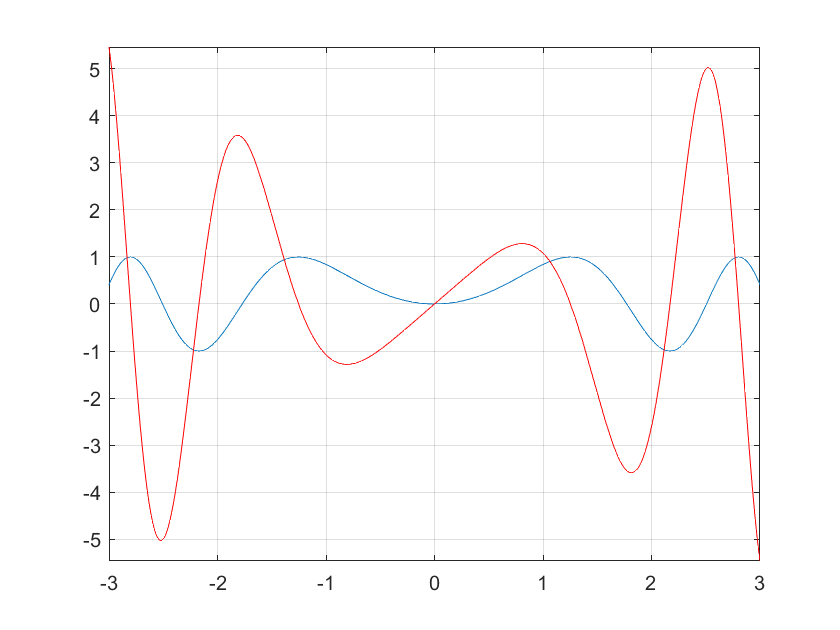

D=[-3 3];
fplot(f,D); hold on; grid on
fplot(Df,D,'r')

% for the specific value 
subs(Df,2)

$$ans = 4\,\cos\left(4\right)$$

double(subs(Df,2))

ans = -2.6146

Or symbolic function be defined 

clear all
syms f(x)
% f(x) = sin(x^2);
f(x) = sin(cos(x));
Df = diff(f,x)
% Df = Df(2)
% double(Df)
whos

- Linear differential equations (homogeneous)

Find the solution to 

           
$$\frac{\textrm{dy}}{\textrm{dt}\;}=-2y$$


clear all
syms t y(t)
D =[0 3];
ode = diff(y(t)) + 2*y(t)== 0;
ySol = dsolve(ode)

$$ySol = C_{1}\,{\mathrm{e}}^{-2\,t}$$

With a specified initial condition, $y\left(0\right)=2$

cond = y(0)==2;
ySol(t) = dsolve(ode,cond)
fplot(ySol(t), D); grid on

With an external input as a constant

        
$$\frac{\textrm{dy}}{\textrm{dt}\;}=-2y+1$$


clear all;
syms t y(t)
ode = diff(y(t),t) + 2*y ==1;
D =[0 3];
cond = y(0)==2;
ySol(t) = dsolve(ode,cond)
fplot(ySol(t),D); grid on
axis([0 3 0 3])

Or  with an external input $\sin \left(t\right)$

    
$$\frac{\textrm{dy}}{\textrm{dt}\;}=-2y+\sin \left(t\right)$$


ode = diff(y(t),t) + 2*y == sin(t)
cond = y(0)==2;
fplot(sin(t),D); hold on; grid on
ySol(t) = dsolve(ode,cond)
fplot(ySol(t),D); grid on
axis([0 3 0 3])

- With an unknown parameter. 

                
$$\frac{\textrm{dy}}{\textrm{dt}\;}=\textrm{ay}$$


where $\textrm{"a"}$ is unknown. 

clear all
syms y(t) a
ode = diff(y(t),t) + a*y== sin(t)
ySol(t) = dsolve(ode)

- **Ex.2 Plot the solution for the different value **$a=1,2,3$

- Here a nonlinear autonomous ODE 

                  
$$\frac{\textrm{dx}}{\textrm{dt}\;}=-x+x^{2\;} \;\;$$


clear variables
syms x(t) t
D=[0 5];
ode = diff(x(t),t) + x(t) - x(t)^2 ==0;
xSol(t) = dsolve(ode)

$$xSol(t) = \left(\begin{array}{c} -\frac{1}{{\mathrm{e}}^{C_{1}+t}-1}\\ 0\\ 1 \end{array}\right)$$

Here there are three solutions to the equation, 


$$x_1 \left(t\right)=0,x_2 \left(t\right)=1,x_3 \left(t\right)=-\frac{1}{\left(e^{\left(C_1 +t\right)} -1\right)}$$


The two are trivial if you substitute them into the ODE, however the third is not convinced. Here the third contains a undetermined variable $C_1 \;$ which is due to undefined initial point. To confirm it is a solution or not, check it

clear all;
syms  C t
f = -1/(exp(C+t)-1);
g=diff(f)

$$g = \frac{{\mathrm{e}}^{C+t}}{{\left({\mathrm{e}}^{C+t}-1\right)}^{2}}$$

h=diff(f)+f-f^2

$$h = \frac{{\mathrm{e}}^{C+t}}{{\left({\mathrm{e}}^{C+t}-1\right)}^{2}}-\frac{1}{{\mathrm{e}}^{C+t}-1}-\frac{1}{{\left({\mathrm{e}}^{C+t}-1\right)}^{2}}$$

Hence the third is also a solution. Let us define the initial point $x\left(0\right)=1$

clear variables;
syms x(t) t
D=[0 5]
ode = diff(x(t),t) + x(t) - x(t)^2 == 0;
cond = x(0)==1; 
xSol(t) = dsolve(ode, cond)

As you may expect from the solution,

$x_1 \left(t=0\right)=0,$ which is the satisfy $x\left(0\right)=1$, hence it is not a solution

$x_2 \left(t=0\right)=1,$ which satisfies $x\left(0\right)=1$, hence it is a solution

$x_3 \left(t=0\right)=-\frac{1}{\left(e^{\left(C_1 +t\right)} -1\right)}{\left|\right.}_{t=0} \;=\;-\frac{1}{e^{C_1 } -1}\;=\;1,$ which satisfies if $e^{C_1 } =0$ 

which means $C_1 =-\infty \;$ which is not a solution. The only solution to this general ODE is $x\left(t\right)=1$. This is one of the difference between L-ODE. 

- **Ex.3 Consider **

         
$$\frac{\textrm{dx}}{\textrm{dt}\;}=-x+x^{2\;} \;\;$$


1) linearize at $x=0$ and check the stability near x=0. Let us define$x\left(0\right)=0\ldotp 0001$. draw the trajectory. 

2) linearize at $x=1$ and check the stability near x=1. Let us define$x\left(1\right)=\;1\ldotp 0001$. draw the trajectory. 

-  If a non-homogeneous case, let us define the external force as constant =1, 1

                        
$$\frac{\textrm{dx}}{\textrm{dt}\;}=-x+x^{2\;} +1$$


Find the solutions 

clear variables
syms x(t) t
D=[0 5];
ode = diff(x(t),t) + x(t) - x(t)^2 ==1;
xSol(t) = dsolve(ode)

Here the solutions are quite different to the homogeneous case!!

- Another non-L ODE

Consider 

           
$$\frac{\textrm{dx}}{\textrm{dt}\;}=-x+x^3$$


clear variables
syms x(t) t
D=[0 5];
ode = diff(x(t),t) + x(t) - x(t)^3 == 0;
xSol(t) = dsolve(ode)

Let us draw a trajectory of the solution with the initial point  $x_0 =1\ldotp 0001$

clear variables
syms x(t) t
D=[0 5];
ode = diff(x(t),t) + x(t) - x(t)^3 == 0;
cond = x(0) == 0.99999
xSol(t) = dsolve(ode, cond)
fplot(xSol(t),D); grid on


Hence this with $x_0 =1\ldotp 0001$will be unbounded as time increase.

**    Ex.4 In the following  cases, regarding stability,  anayize with different initial conditions as**

**1) **$x_0 =0\ldotp 9999$

2) $x_0 =0\ldotp 0001$

3)${\;x}_0 =0\ldotp 5$